# 数据类型：结构体

当有按名称组织的数据时，可以用结构体来存储这些数据。

clear;clc;close all;
Prename=string(0:0.3:1.8);
N=numel(Prename);
Pretitle=repmat("Data\Vgs=xxxV.csv",1,N);
T_name=replaceBetween(Pretitle,"=","V",Prename);
T=struct();
field_name=strings(1,N);
% 定义N个字段，每个字段为一个表格数据
for i = 1:N
    field_name(i)='V'+replace(Prename(i),'.','_');
	data_table=readtable(T_name(i),"VariableNamingRule","preserve");
	data_table.Properties.VariableNames=["Vds" "Ids"];
	T.(field_name(i))=data_table;
end

% ===================== 【完全仿照你的风格】绘图代码 =====================
figure;
hold on; 

% 1. 颜色映射（和你代码一致）
cmap = lines(length(field_name)); 
legend_list = {}; % 图例列表

% 2. 循环绘图（完全复刻你的for循环格式）
for i = 1:length(field_name)
    % 读取当前数据
    data_table = T.(field_name(i));
    x = data_table.Vds;        % 横坐标 Vds
    Id = data_table.Ids;       % 纵坐标 Ids
    
    % 画图（参数和你完全一致：LineWidth=1.8）
    plot(x, Id, 'LineWidth', 1.8, 'Color', cmap(i,:));
    
    % 图例（和你格式一致：去掉后缀，直接用电压名）
    legend_list{i} = strrep(field_name(i), '_', '.'); 
end

% 3. 标注（完全复刻你的格式）
title('MOSFET Input Characteristics', 'FontSize',14);
xlabel('V_{GS} (V)', 'FontSize',12);
ylabel('Drain Current I_D (A)', 'FontSize',12);
legend(["V0", "V0.3", "V0.6", "V0.9", "V1.2", "V1.5", "V1.8"], "FontSize", 10, "Interpreter", "none", "Position", [0.1870 0.6473 0.0928, 0.2194])
set(gca,'FontSize',10);

disp('绘图完成！');

绘图完成！


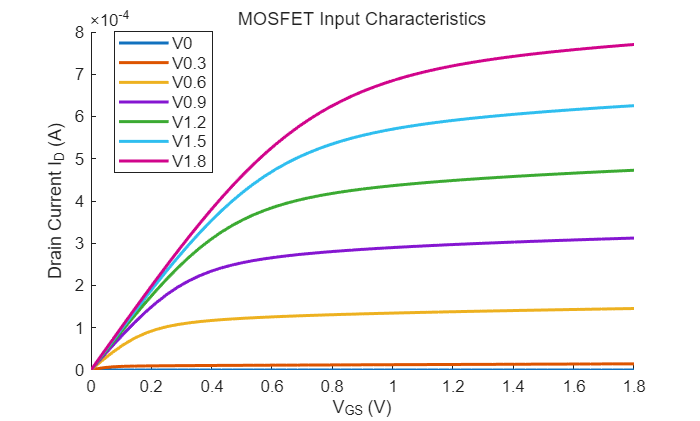

hold off;

matlab2tikz('showInfo', false, 'strict', true,'fig_inputcurve.tex')